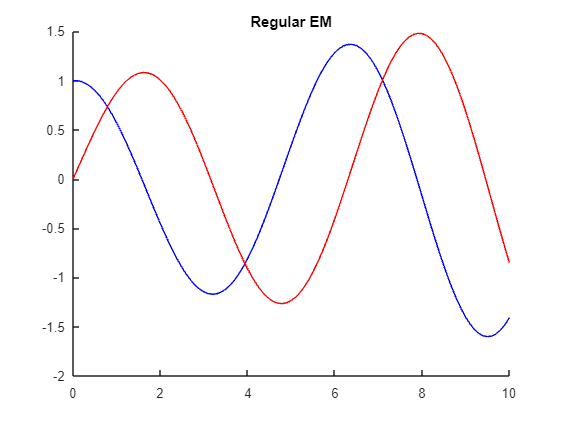

A = [0 -1; 1 0];
x_0 = 1;
y_0 = 0;
T = 10;
N = 100;
x = []; y = []; t = [];
[x, y,t] = EMsolver(A, x_0, y_0, T, N);
title("Regular EM")
hold on
plot(t,x, "blue")
plot(t,y, "red")
hold off

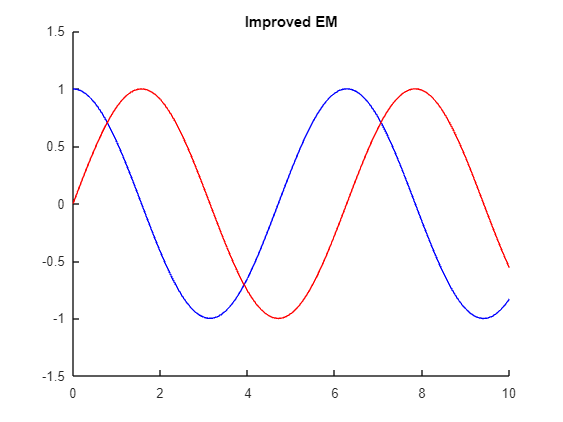

figure
hold on
x = []; y = []; t = [];
[x, y,t] = IEMsolver(A, x_0, y_0, T, N);
title("Improved EM")
plot(t,x, "blue")
plot(t,y, "red")
hold off

function [x,y,t] = EMsolver(A,x_0,y_0,T,N) 
 
    dt = T/N; 
    t = 0:dt:T; 
     
    SOL = NaN(2,length(t)); 
    SOL(1,1) = x_0; 
    SOL(2,1) = y_0; 
     
    for(k = 2:length(t)) 
        SOL(:,k) = SOL(:,k-1) + dt*A*SOL(:,k-1); 
    end 
     
    x = SOL(1,:); 
    y = SOL(2,:); 
end 

function [x,y,t] = IEMsolver(A,x_0,y_0,T,N) 
 
    dt = T/N; 
    t = 0:dt:T; 
     
    SOL = NaN(2,length(t)); 
    SOL(1,1) = x_0; 
    SOL(2,1) = y_0; 
     
    for(k = 2:length(t)) 
        mL = A*SOL(:,k-1);
        mR = A*(SOL(:,k-1) + dt*mL);
        SOL(:,k) = SOL(:,k-1) + dt/2 * (mL + mR);
    end 
     
    x = SOL(1,:); 
    y = SOL(2,:); 
end 
 
